# Mobile robot short Project

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Loading environment

clear
close all
clf

load("Encoder_Data.mat")

load("Sensors_Data.mat")

## Pose estimation given encoder data (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

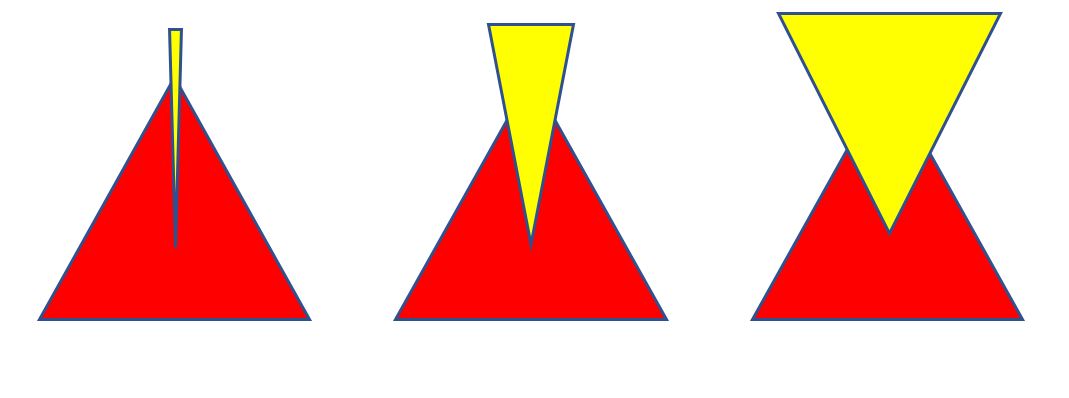

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

ProcNoiseTheta = 9.0000e-06

Ts = 0.0200

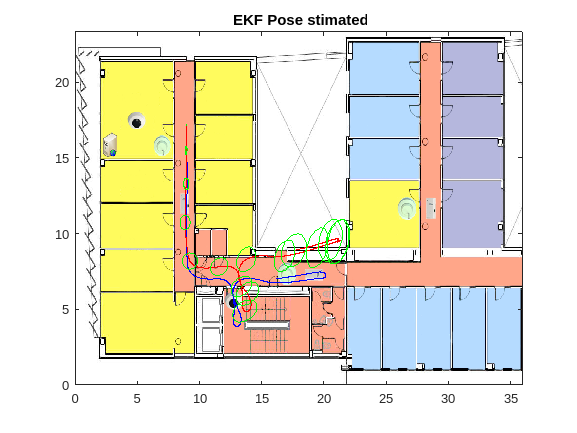

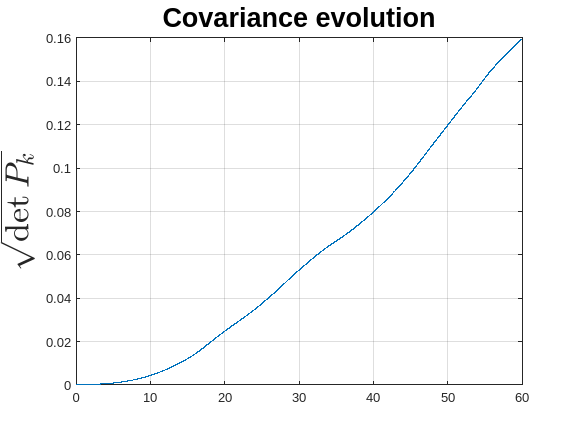

% Add your code here
sim("EKF_Pose_estimation_1.slx" )

### 1.a) Pose_theoric, assuming no noise

r = 0.1;
time = Ts;
t = R_acu(:,1);
L_inc = diff(L_acu(:,2))

L_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


R_inc = diff(R_acu(:,2))

R_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


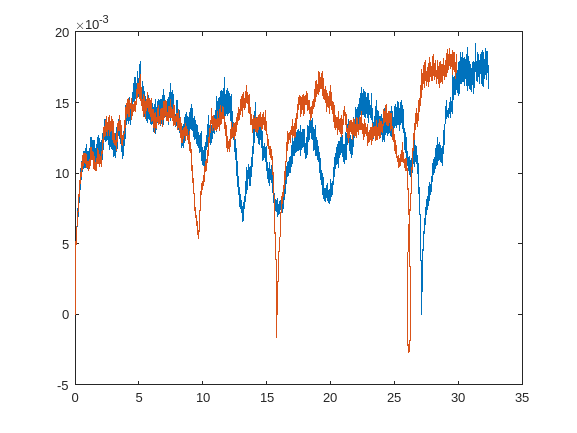


delta_d=(R_inc+L_inc)/2;
delta_t=(R_inc-L_inc)/(W);

plot(R_acu(2:3004,2),R_inc(:))
hold on
plot(L_acu(2:3004,2), L_inc(:))

### Odometry displacement 

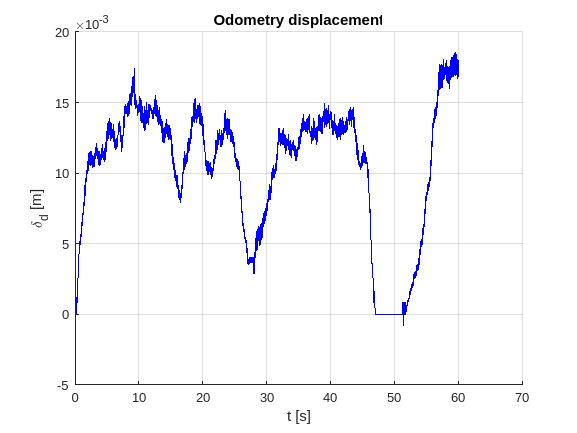

figure
hold on
grid on
title('Odometry displacement');
xlabel ('t [s]');
ylabel ('\delta_d [m]')
plot(t(2:end),delta_d,'b');

**Theoric trajectory calculation**

Initial_pose=transl(0,0,0)*trotz(-pi/2);
Initial_position=transl(Initial_pose);
Initial_orientation=-pi/2;
x(1)=Initial_position(1);
y(1)=Initial_position(2);
o(1)=Initial_orientation;
for i=1:(length(t)-1)
    x(i+1) = x(i)+delta_d(i)*cos(o(i));
    y(i+1) = y(i)+delta_d(i)*sin(o(i));
    o(i+1) = mod(o(i)+delta_t(i),2*pi);
end

### 1.b) Pose_estimation by adding noise in odometry

noise_std = 0.002; % adjust as needed
ProcNoiseTheta

ProcNoiseTheta = 9.0000e-06

ProcNoiseD

ProcNoiseD = 3.6100e-04

delta_d_n = delta_d + randn(length(t)-1,1)*noise_std;
delta_t_n = delta_t + randn(length(t)-1,1)*noise_std;

**Odometry displacement with noise**

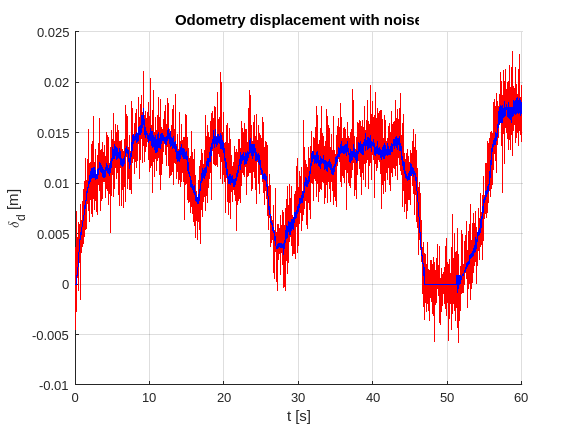

figure
hold on

plot(t(2:end),delta_d_n,'r')
xlim ([0 Tf])
grid on
title('Odometry displacement with noise')
xlabel ('t [s]')
ylabel ('\delta_d [m]')
plot(t(2:end),delta_d,'b')

**Estimated (noisy) trajectory calculation**

x_n(1)=Initial_position(1);
y_n(1)=Initial_position(2);
o_n(1)=Initial_orientation;
for i=1:(length(t)-1)
    x_n(i+1) = x_n(i)+delta_d_n(i)*cos(o_n(i));
    y_n(i+1) = y_n(i)+delta_d_n(i)*sin(o_n(i));
    o_n(i+1) = mod(o_n(i)+delta_t_n(i),2*pi);
end

### 1.c) Ricatti equation

V = [ProcNoiseD 0; 0 ProcNoiseTheta];
F_x(:,:,i)= [1 0 -delta_d(1)*sin(o(1));....
                 0 1  delta_d(1)*cos(o(1));....
                 0 0 1];
F_v(:,:,i) = [cos(o(1)) 0;sin(o(1)) 0;0 1];
P(:,:,i) = F_x(:,:,1)*(eye(3)*0.0001)*F_x(:,:,1)' + F_v(:,:,1)*...
           [V(1) 0; 0 V(2,2)]*F_v(:,:,1)';
for i=2:(length(t))-1
    F_x(:,:,i) = [1 0 -delta_d(i) * sin(o(i)); 0 1 delta_d(i) * cos(o(i)); 0 0 1];
    F_v(:,:,i) = [cos(o(i)) 0; sin(o(i)) 0; 0 1];
    P(:,:,i) = F_x(:,:,i)*P(:,:,i-1)*F_x(:,:,i)' + F_v(:,:,i)*[V(1) 0; 0 V(2,2)]*F_v(:,:,i)';
end

**Covariance evolution**

for i=2:length(P)
    a(i)=sqrt(det(P(:,:,i)));
end

figure
grid on
plot((0:0.02:3002*0.02),a)

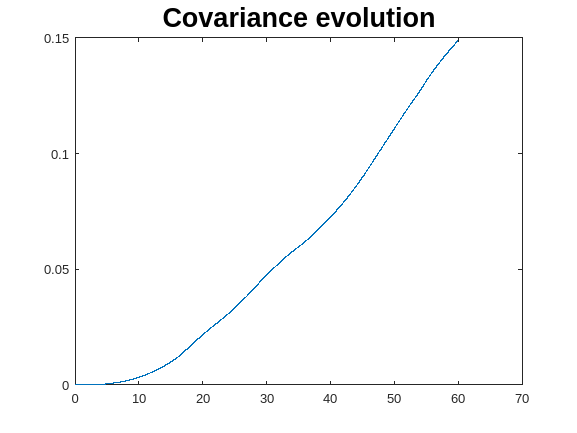

title ('Covariance evolution',"FontSize",20)

### 2.a) x,y poses for both trajectories: theoric and estimated

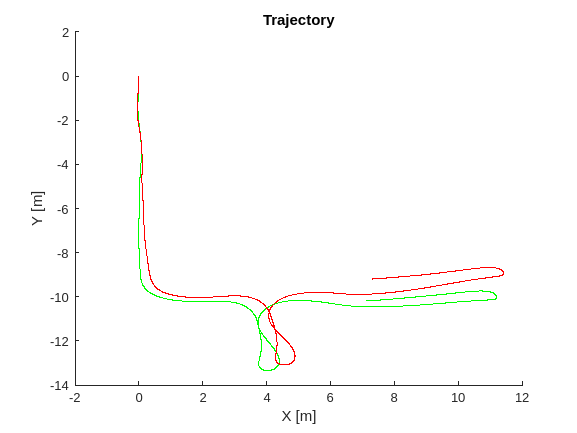

figure
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y,'g')
plot(x_n,y_n,'r')

### 2.b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

figure
hold on
plot(x,y,'g')
plot(x_n,y_n,'r')

hold on
for i=1:round(length(t)/15):length(t)
    plot_ellipse(P(1:2,1:2,i),[x_n(i), y_n(i)],'b');
    title('EKF Pose stimated');
end

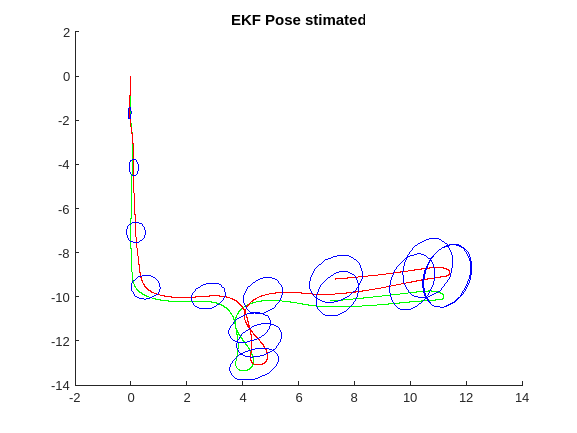

hold off

### 2.c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

vidwriter = VideoWriter('RobotUncertaintyAngle.avi', 'Motion JPEG AVI');
vidwriter.FrameRate = 50;
open(vidwriter);
for i=1:length(F)
    writeVideo(vidwriter, F(i));
end
close(vidwriter)

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
for i=1:length(x)-1
    clf
    figure(1)
    grid on
    hold on
    title('Trajectory')
    xlabel ('X [m]')
    ylabel ('Y [m]')
    xlim([7,22])
    ylim([3,18])
    plot(x,y,'g')
    plot(x_n,y_n,'r')

    robotPosition = (transl(x(i),y(i),0)*trotz(o(i))*Robot')';
    robotTriangle = polyshape(robotPosition(:,1),robotPosition(:,2));
    plot(robotTriangle,'FaceColor','r','FaceAlpha',1);
    u = (sin(P(3,3,i)/2)+0.0001)*20;
    Cone = [0.1 0 0 1; 0.5 u 0 1; 0.5 -u 0 1];
    conePosition = (transl(x(i),y(i),0)*trotz(o(i))*Cone')';
    coneTriangle = polyshape(conePosition(:,1),conePosition(:,2));
    plot(coneTriangle,'FaceColor','y','FaceAlpha',1);
    drawnow;
    F(i) = getframe(gcf);
end

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectoryies appear as the robot moves.

% Add your code here

## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

Lmk= [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1];

### Plot Land Marks 

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];


### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

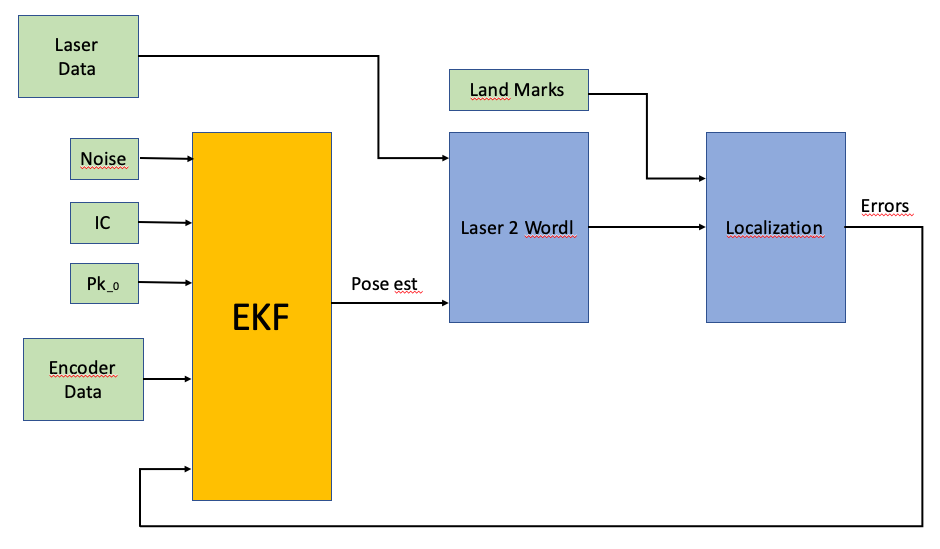

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory.

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

% Add your code here